# UR5e Control for RoboCup ARM Challenge

## Setup the Virtual Simulation Environment

[**Instructions to setup RoboCup ARM provided virtual machine**](https://drive.google.com/file/d/1w9tBy3DKmZBKEfOqOFUXcT8hcQig6sNS/view)** (Appendix A)**

Follow the instructions above to setup the MathWorks provided Virtual Machine in your computer.

Find and open one of the environments for the RoboCup ARM Challenge. Note that there is more than on environment provided to ilustrate how objects in the environments are subject to changing positions and orientations based on the challenge instructions. 

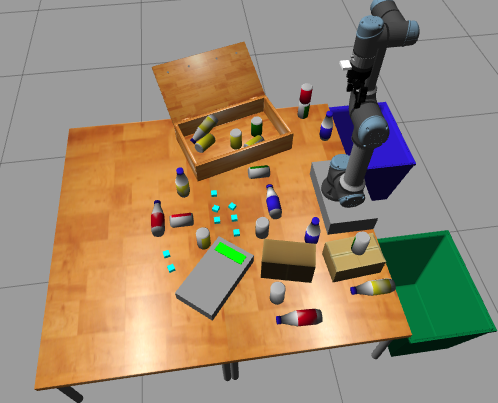

#### Connect MATLAB to Gazebo using the ROS Toolbox

Start a ROS node from MATLAB to interact with the Gazebo environment. For more information on interaction with the ROS ecosystem from MATLAB visit [Getting Started with ROS Toolbox](https://www.mathworks.com/help/ros/getting-started-with-ros-toolbox.html).

If you are having trouble with this step, or if you are waiting a long time for the nodes to communicate, try using the commented code in line 4. The IP address to be specified is the wireless network adapter address.

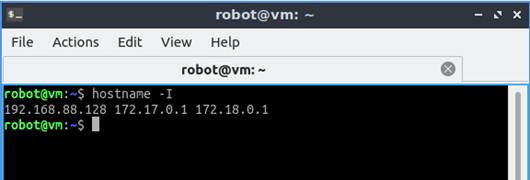

rosIP = "192.168.56.101"; % Change IP address!!    % IP address of ROS enabled machine  
rosshutdown; % shut down existing connection to ROS
rosinit(rosIP,11311);

Initializing global node /matlab_global_node_68983 with NodeURI http://192.168.56.1:53525/ and MasterURI http://192.168.56.101:11311.


% rosinit(rosIP,'NodeHost','172.31.201.75') % Try specifying node host IP in case that there are multiple network adapters
% rosinit(rosIP,11311,'NodeHost','192.168.68.123');

## Control Gripper Using ROS Action Client

Initialize ROS action client.

[gripAct,gripGoal] = rosactionclient('/gripper_controller/follow_joint_trajectory','control_msgs/FollowJointTrajectory','DataFormat','struct')

gripAct =   SimpleActionClient with properties:

           ActionName: '/gripper_controller/follow_joint_trajectory'
           ActionType: 'control_msgs/FollowJointTrajectory'
    IsServerConnected: 0
                 Goal: [1×1 FollowJointTrajectoryGoal]
            GoalState: ''
        ActivationFcn: @(~)disp('Goal active')
          FeedbackFcn: @(~,msg)disp(['Feedback: ',showDetailsAnyFormat(msg)])
            ResultFcn: @(~,res)disp(['Final state ',res.State,' with result: ',showDetailsAnyFormat(res.Message)])
           DataFormat: 'object'


gripGoal =   ROS FollowJointTrajectoryGoal message with properties:

          MessageType: 'control_msgs/FollowJointTrajectoryGoal'
           Trajectory: [1×1 JointTrajectory]
        PathTolerance: [0×1 JointTolerance]
        GoalTolerance: [0×1 JointTolerance]
    GoalTimeTolerance: [1×1 Duration]

  Use showdetails to show the contents of the message


gripAct.FeedbackFcn = [];
gripAct.ResultFcn = [];

Pack ROS message and send goal to gripper controller.

gripPos = 0.035; %0 is fully closed, 4 is fully open
gripGoal=packGripGoal(gripPos,gripGoal)

gripGoal =   ROS FollowJointTrajectoryGoal message with properties:

          MessageType: 'control_msgs/FollowJointTrajectoryGoal'
           Trajectory: [1×1 JointTrajectory]
        PathTolerance: [0×1 JointTolerance]
        GoalTolerance: [1×1 JointTolerance]
    GoalTimeTolerance: [1×1 Duration]

  Use showdetails to show the contents of the message


sendGoal(gripAct,gripGoal);

## Control Gripper Position using ROS Action Client

### Initialize ROS Action Client

[trajAct,trajGoal] = rosactionclient('/pos_joint_traj_controller/follow_joint_trajectory','control_msgs/FollowJointTrajectory','DataFormat','struct') 

trajAct =   SimpleActionClient with properties:

           ActionName: '/pos_joint_traj_controller/follow_joint_trajectory'
           ActionType: 'control_msgs/FollowJointTrajectory'
    IsServerConnected: 0
                 Goal: [1×1 FollowJointTrajectoryGoal]
            GoalState: ''
        ActivationFcn: @(~)disp('Goal active')
          FeedbackFcn: @(~,msg)disp(['Feedback: ',showDetailsAnyFormat(msg)])
            ResultFcn: @(~,res)disp(['Final state ',res.State,' with result: ',showDetailsAnyFormat(res.Message)])
           DataFormat: 'object'


trajGoal =   ROS FollowJointTrajectoryGoal message with properties:

          MessageType: 'control_msgs/FollowJointTrajectoryGoal'
           Trajectory: [1×1 JointTrajectory]
        PathTolerance: [0×1 JointTolerance]
        GoalTolerance: [0×1 JointTolerance]
    GoalTimeTolerance: [1×1 Duration]

  Use showdetails to show the contents of the message


trajAct.FeedbackFcn = []; 
trajAct.ResultFcn = []; 
jointSub = rossubscriber("/joint_states",'DataFormat','struct')

jointSub =   Subscriber with properties:

                      TopicName: '/joint_states'
                  LatestMessage: [0×1 JointState]
                    MessageType: 'sensor_msgs/JointState'
                     BufferSize: 1
    MessagePreprocessingEnabled: 0
                  NewMessageFcn: []
                     DataFormat: 'object'


jointStateMsg = jointSub.LatestMessage

jointStateMsg =   0×1 ROS JointState message array with properties:

    MessageType
    Header
    Name
    Position
    Velocity
    Effort


### Setup Robot Model for Inverse Kinematics

The ROS Action that controls the robot uses the position of the individual joints as an input. In roder to make it easier to establish a cartesian target location it is necessary to have a robot model for which to [calculate the inverse kinmetics.](https://www.mathworks.com/help/robotics/ref/inversekinematics-system-object.html)

UR5e = loadrobot('universalUR5e')

UR5e =   rigidBodyTree with properties:

     NumBodies: 10
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'base'  'base_link_inertia'  'shoulder_link'  'upper_arm_link'  'forearm_link'  'wrist_1_link'  'wrist_2_link'  'wrist_3_link'  'flange'  'tool0'}
      BaseName: 'base_link'
       Gravity: [0 0 0]
    DataFormat: 'struct'


initialIKGuess = homeConfiguration(UR5e);

% Adjust body transformations from previous URDF version
tform=UR5e.Bodies{3}.Joint.JointToParentTransform;
UR5e.Bodies{3}.Joint.setFixedTransform(tform*eul2tform([pi/2,0,0]));
tform=UR5e.Bodies{4}.Joint.JointToParentTransform;
UR5e.Bodies{4}.Joint.setFixedTransform(tform*eul2tform([-pi/2,0,0]));
tform=UR5e.Bodies{7}.Joint.JointToParentTransform;
UR5e.Bodies{7}.Joint.setFixedTransform(tform*eul2tform([-pi/2,0,0]));

ik = inverseKinematics("RigidBodyTree",UR5e); % Create Inverse kinematics solver

ikWeights = [0.25 0.25 0.25 0.1 0.1 .1]; % configuration weights for IK solver [Translation Orientation] see documentation
jointStateMsg = receive(jointSub,3) % receive current robot configuration

jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


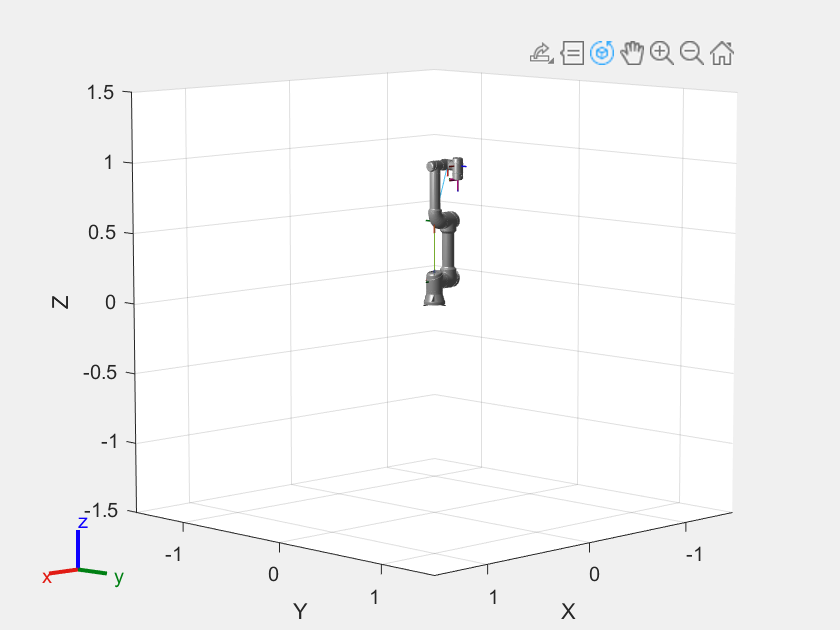

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties



initialIKGuess(1).JointPosition = jointStateMsg.Position(4); % update configuration in initial guess
initialIKGuess(2).JointPosition = jointStateMsg.Position(3);
initialIKGuess(3).JointPosition = jointStateMsg.Position(1);
initialIKGuess(4).JointPosition = jointStateMsg.Position(5);
initialIKGuess(5).JointPosition = jointStateMsg.Position(6);
initialIKGuess(6).JointPosition = jointStateMsg.Position(7);
show(UR5e,initialIKGuess)

### Set End-Effector Pose

This section has interactive controls to set the cartesian position of the robot end-effector and use the inverse kinematics solver to calculate teh necessary robot configuration.

gripperX = 0.13;
gripperY = 0.56;
gripperZ = 0.4;

gripperTranslation = [gripperX gripperY gripperZ];
gripperRotation = [-pi/2 -pi 0]; %  [Z Y X]radians


tform = eul2tform(gripperRotation); %
tform(1:3,4) = gripperTranslation'; % set translation in homogeneous transform

[configSoln, solnInfo] =ik('tool0',tform,ikWeights,initialIKGuess)

configSoln = 1×6 struct array with fields:
    JointName
    JointPosition


solnInfo = struct with fields:
           Iterations: 50
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1524e-09
             ExitFlag: 1
               Status: 'success'


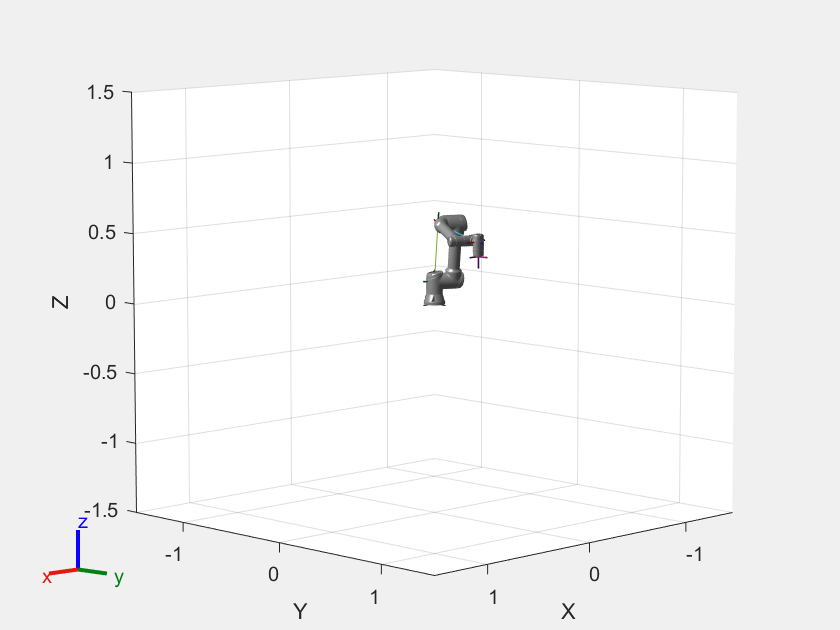

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties



show(UR5e,configSoln)

### Send Joint Trajectory Goal 

Packing the robot configuration into the appropriate ROS Action goal message and sending it to the robot controller.

UR5econfig = [configSoln(3).JointPosition configSoln(2).JointPosition configSoln(1).JointPosition...
    configSoln(4).JointPosition configSoln(5).JointPosition configSoln(6).JointPosition];
trajGoal = packTrajGoal(UR5econfig,trajGoal)

trajGoal =   ROS FollowJointTrajectoryGoal message with properties:

          MessageType: 'control_msgs/FollowJointTrajectoryGoal'
           Trajectory: [1×1 JointTrajectory]
        PathTolerance: [0×1 JointTolerance]
        GoalTolerance: [6×1 JointTolerance]
    GoalTimeTolerance: [1×1 Duration]

  Use showdetails to show the contents of the message


sendGoal(trajAct,trajGoal); 

## Receive Camera Image Using ROS Subscriber

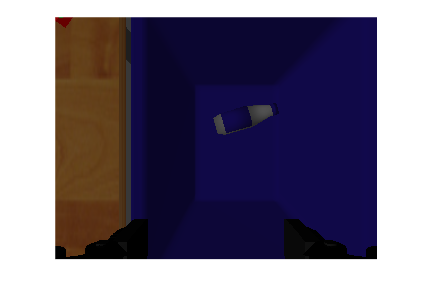

rgbImgSub = rossubscriber("/camera/rgb/image_raw","sensor_msgs/Image","DataFormat","struct");
pause(1)
curImage = receive(rgbImgSub,3);
rgbImg = rosReadImage(rgbImgSub.LatestMessage); 
imshow(rgbImg)

## Receive Depth Image Using ROS Subscriber

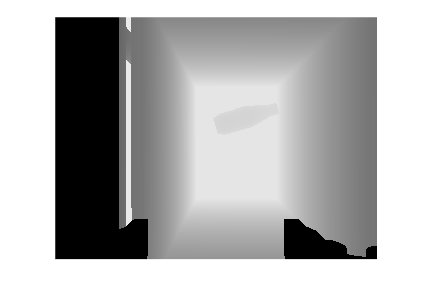

rgbDptSub = rossubscriber('/camera/depth/image_raw',"sensor_msgs/Image","DataFormat","struct");
pause(1)
curDepth = receive(rgbDptSub,3);
depthImg = rosReadImage(rgbDptSub.LatestMessage); 
imshow(depthImg)

### Appendix - Utilities

This section contains two functions that can be reused for packing the goal information for the ROS action goals to the appropriate message structures.

function gripGoal=packGripGoal(pos,gripGoal)
    jointWaypointTimes = 3;
    jointWaypoints = [pos]';
    numJoints = size(jointWaypoints,1);
    gripGoal.Trajectory.JointNames = {'robotiq_85_left_knuckle_joint'};
    gripGoal.GoalTolerance = rosmessage('control_msgs/JointTolerance','DataFormat','struct');
    gripGoal.GoalTolerance.Name = gripGoal.Trajectory.JointNames{1};
    gripGoal.GoalTolerance.Position = 0;
    gripGoal.GoalTolerance.Velocity = 0.1;
    gripGoal.GoalTolerance.Acceleration = 0.1;
    
    trajPts = rosmessage('trajectory_msgs/JointTrajectoryPoint','DataFormat','struct');
    trajPts.TimeFromStart = rosduration(jointWaypointTimes,'DataFormat','struct');
    trajPts.Positions = jointWaypoints;
    trajPts.Velocities = zeros(size(jointWaypoints));
    trajPts.Accelerations = zeros(size(jointWaypoints));
    trajPts.Effort = zeros(size(jointWaypoints));
    
    gripGoal.Trajectory.Points = trajPts;
end

function trajGoal = packTrajGoal(config,trajGoal)
    jointWaypointTimes = 3;
    jointWaypoints = config';
    numJoints = size(jointWaypoints,1);
    
    trajGoal.Trajectory.JointNames = {'elbow_joint','shoulder_lift_joint','shoulder_pan_joint','wrist_1_joint','wrist_2_joint','wrist_3_joint'};
    
    for idx = 1:numJoints
    
        trajGoal.GoalTolerance(idx) = rosmessage('control_msgs/JointTolerance','DataFormat','struct');
        trajGoal.GoalTolerance(idx).Name = trajGoal.Trajectory.JointNames{idx};
        trajGoal.GoalTolerance(idx).Position = 0;
        trajGoal.GoalTolerance(idx).Velocity = 0;
        trajGoal.GoalTolerance(idx).Acceleration = 0;
    
    end
    
    trajPts = rosmessage('trajectory_msgs/JointTrajectoryPoint','DataFormat','struct');
    trajPts.TimeFromStart = rosduration(jointWaypointTimes,'DataFormat','struct');
    trajPts.Positions = jointWaypoints;
    trajPts.Velocities = zeros(size(jointWaypoints));
    trajPts.Accelerations = zeros(size(jointWaypoints));
    trajPts.Effort = zeros(size(jointWaypoints));
    
    trajGoal.Trajectory.Points = trajPts;
end